# IIR Zero-Pole Plot

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the data.

[whaley,fs] = audioread("./data/whalesound.wav");

## Task 1

In this activity, you'll look at the filter responses of two IIR filters. For both filters, the magnitude response looks reasonable.

To check for filter stability, look at the zero-pole plot. For the first coefficient vector `a`, the pole is inside the unit circle. For the second coefficient vector `a`, there is a pole located outside the unit circle.

biir = [0.5 0.25]

biir =     0.5000    0.2500


aiir = [1 -1.2]

aiir =     1.0000   -1.2000


View frequency response

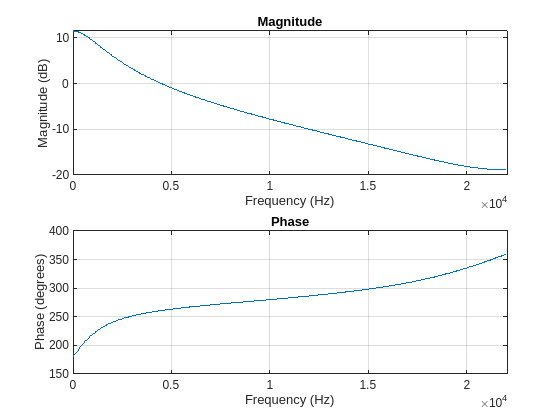

freqz(biir,aiir,[],fs)

View zero-pole plot

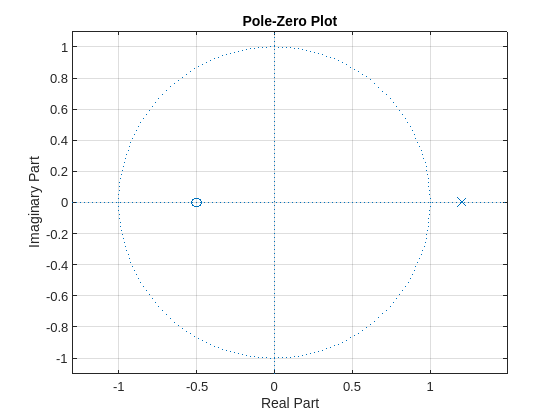

[z,p,k] = tf2zpk(biir,aiir);
zplane(z,p)
grid on

View largest pole value. `max(abs(p))` should be less than 1.

max(abs(p))

ans = 1.2000

View filtered signal

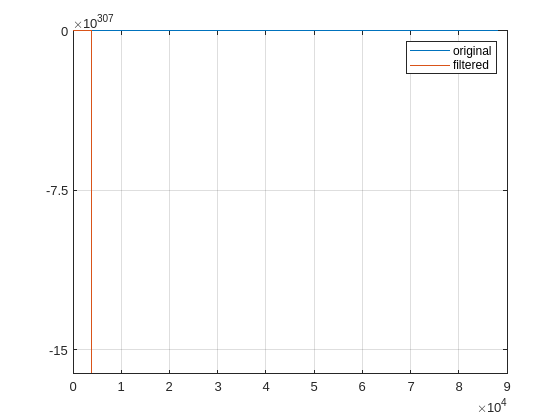

whalefilt = filter(biir,aiir,whaley);
plot(whaley)
grid on
hold on
plot(whalefilt)
hold off
legend("original","filtered")